# Test My DWT for EEG

load("EEG_test.mat") ; % X : signal, Fs : sampling rate
if length(X) < 2^7
    error("The length of signal is too short!") ;
end
temp = floor(length(X) / 2^7) ;
temp = length(X) - 2^7 * temp ;
temp1 = floor(temp/2) ;
temp2 = ceil(temp/2) ;
X = X(1 + temp1 : end - temp2) ;

M = length(X) - 1 ;
[P,S,t0_P,t0_S,omega_0] = Get_my_dwt_wavelet(M,Fs) ;
W = cell(8,2) ;
W{1,2} = X ;
for i = 2:8
    [W{i,1},W{i,2}] = My_DWT_for_EEG(W{i-1,2},P,S,t0_P,t0_S) ;
end

disp("Approx") ;

Approx


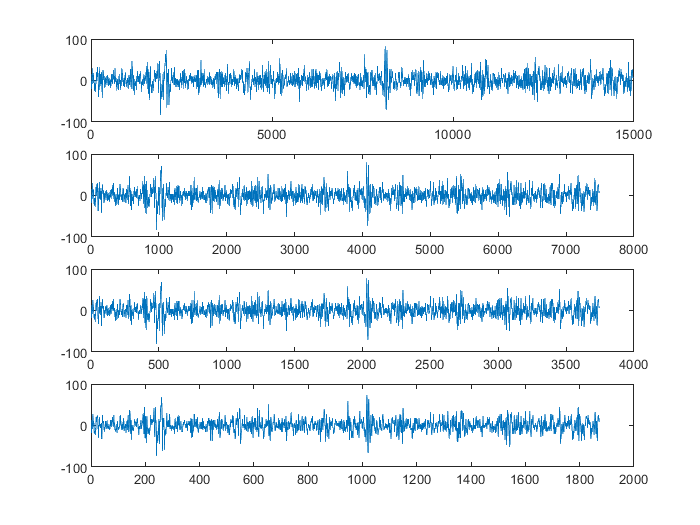

figure();
for i = 1:4
    subplot(4,1,i) ;
    plot(W{i,2}) ;
end

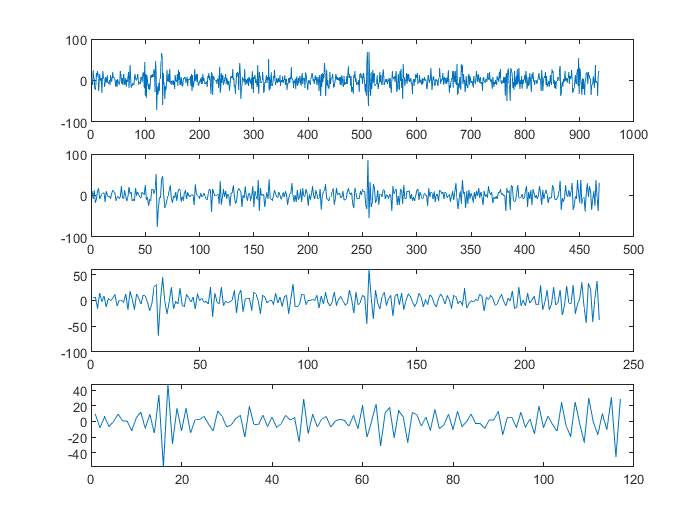

figure();
for i = 1:4
    subplot(4,1,i) ;
    plot(W{i+4,2}) ;
end

disp("Detail") ;

Detail


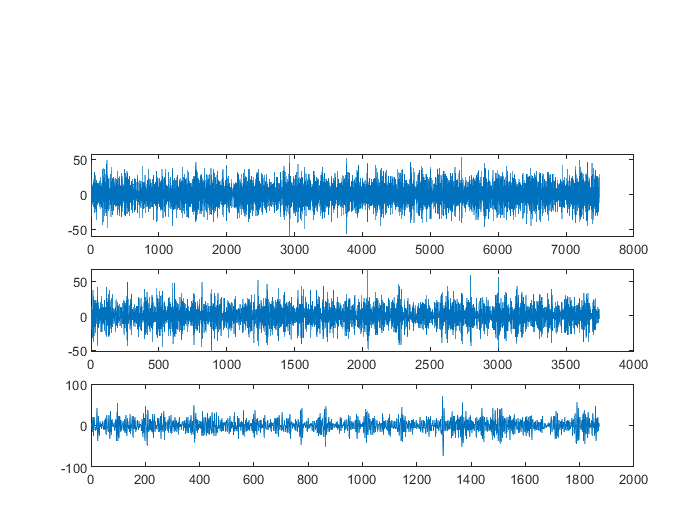

figure();
for i = 2:4
    subplot(4,1,i) ;
    plot(W{i,1}) ;
end

figure() ;
for i = 1:4
    subplot(4,1,i) ;
    plot(W{i+4,2}) ;
end

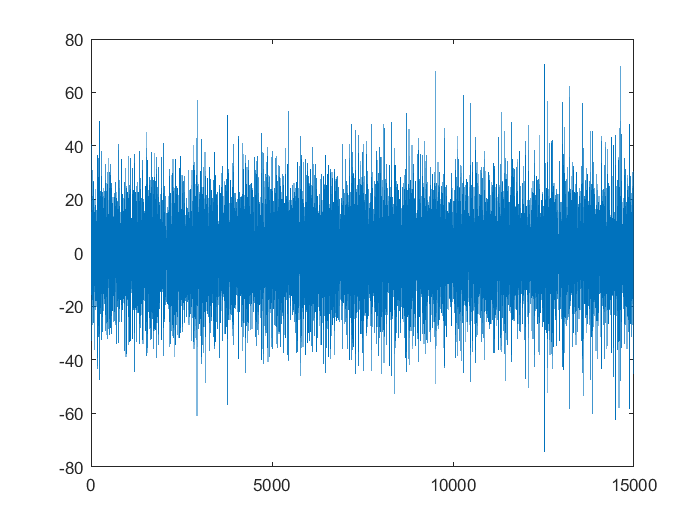


figure();
W = [W(2:end,1) ; W(end,2)] ;
W = cell2mat(W) ;
plot(W) ;